# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.10 Mesh同伦变换

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)  [**自定义colormap**](https://zhuanlan.zhihu.com/p/489920741)

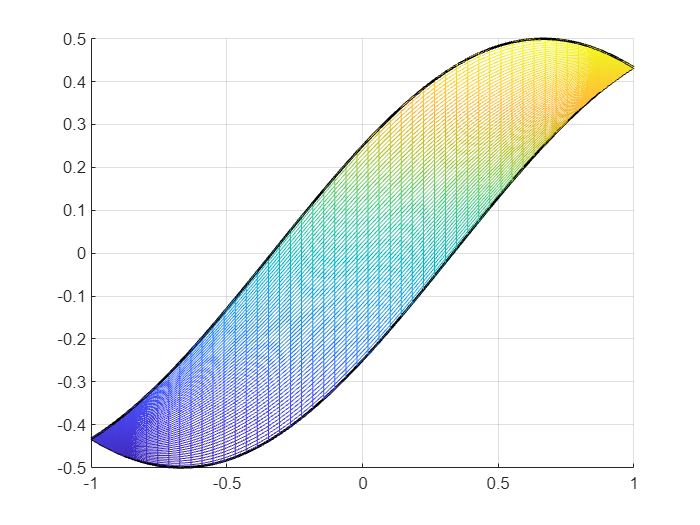

clear;clc;
xx = linspace(-1, 1, 50);
[xi, eta] = meshgrid(xx);
f = @(x) sin(x*pi/2 + pi/6) / 2;
g = @(x) sin(x*pi/2 - pi/6) / 2;
y = g(xi) .* (1 - eta) / 2 + f(xi) .* (1 + eta) / 2;
x = xi;
mesh(x, y, y);
view([0, 0, 1]);
hold on
plot3(xx, f(xx), f(xx), 'k', 'LineWidth', 1.5);
plot3(xx, g(xx), g(xx), 'k', 'LineWidth', 1.5);
hold off